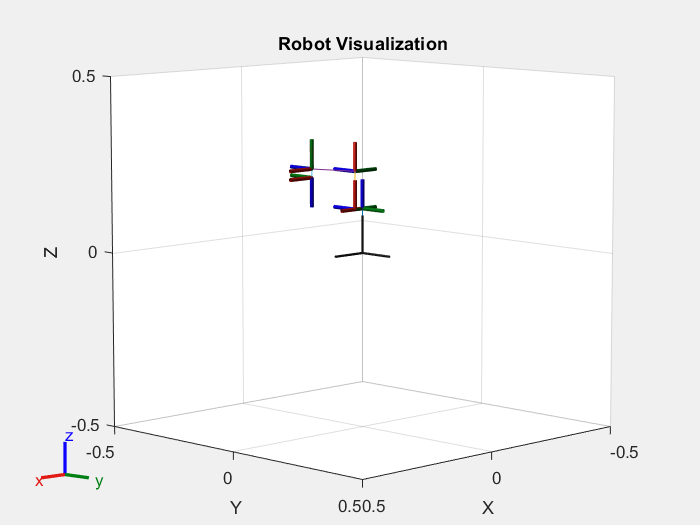

clc;
clear all;

% Create a rigid body tree model for the robot
robot = rigidBodyTree('DataFormat', 'column');

% Define rigid bodies
arm1 = rigidBody("arm1");
arm2 = rigidBody("arm2");
arm3 = rigidBody("arm3");
arm4 = rigidBody("arm4");
arm5 = rigidBody("arm5");
arm6 = rigidBody("arm6");

% Define collision objects for each part
collisionBox1 = collisionCylinder(0.08, 0.1); 
collisionBox2 = collisionCylinder(0.04, 0.127);
collisionBox3 = collisionBox(0.108, 0.02969, 0.02969);
collisionBox4 = collisionCylinder(0.02, 0.04); 
collisionBox5 = collisionCylinder(0.02, 0.16898); 
collisionBox6 = collisionCylinder(0.02, 0.04); 
collisionBox7 = collisionCylinder(0.01, 0.02429); 

% Define transformations for collision objects
tform1 = trvec2tform([0, 0, +0.05]);
tform2 = trvec2tform([0, 0, -0.127 / 2]);
tform3 = trvec2tform([0.108 / 2, 0, 0]);
tform4 = trvec2tform([0, 0, 0]);
tform5 = trvec2tform([0, 0, -0.16898 / 2]);
tform6 = trvec2tform([0, 0, 0]);
tform7 = trvec2tform([0, 0, 0]);

% Add collision objects to the rigid bodies
addCollision(robot.Base, collisionBox1, tform1);
addCollision(arm1, collisionBox2, tform2);
addCollision(arm2, collisionBox3, tform3);
addCollision(arm3, collisionBox4, tform4);
addCollision(arm4, collisionBox5, tform5);
addCollision(arm5, collisionBox6, tform6);
addCollision(arm6, collisionBox7, tform7);

% Define joints
jnt1 = rigidBodyJoint("jnt1", "revolute");
jnt2 = rigidBodyJoint("jnt2", "revolute");
jnt3 = rigidBodyJoint("jnt3", "revolute");
jnt4 = rigidBodyJoint("jnt4", "revolute");
jnt5 = rigidBodyJoint("jnt5", "revolute");
jnt6 = rigidBodyJoint("jnt6", "revolute");

% Define DH parameters this one may have some problems
% dhparams = [
%     0        0        0.127   0;
%     0.02969  pi/2     0       0;
%     0.108    0        0       0;
%     0.020   -pi/2     0.16898 0;
%     0        pi/2     0       pi/2;
%     0        pi/2     0.02429 0
% ];

dhparams = [
    0,        0,        0.127,       0;
    0.02969,       pi/2,     0,        0;
    0.108,       0,        0,        0;
    0.020,       pi/2,     0.16898,       0;
    0,       -pi/2,     0,        0;
    0,        pi/2,     0.02429,       0;
    ];

% Add rigid bodies and joints to the robot
bodies = {arm1, arm2, arm3, arm4, arm5, arm6};
joints = {jnt1, jnt2, jnt3, jnt4, jnt5, jnt6};
for i = 1:numel(bodies)
    setFixedTransform(joints{i}, dhparams(i, :), "mdh");
    bodies{i}.Joint = joints{i};
    if i == 1
        addBody(robot, bodies{i}, robot.Base.Name);
    else
        addBody(robot, bodies{i}, bodies{i - 1}.Name);
    end
end

% Visualize the robot in its home configuration
homeconfig = [0; pi/2; 0; 0; -pi/2; 0];

figure;
show(robot, homeconfig, "Collisions", "off");
title('Robot Visualization');




% Define symbolic variables for Jacobian and trajectory computation
syms theta1 theta2 theta3 theta4 theta5 theta6 real
joint_angles = [theta1; theta2; theta3; theta4; theta5; theta6];

% Forward kinematics computation
T = eye(4);
for i = 1:numel(joint_angles)
    a = dhparams(i, 1);
    alpha = dhparams(i, 2);
    d = dhparams(i, 3);
    theta = joint_angles(i);
    Ti = [
        cos(theta), -sin(theta), 0, a;
        sin(theta) * cos(alpha), cos(theta) * cos(alpha), -sin(alpha), -sin(alpha) * d;
        sin(theta) * sin(alpha), cos(theta) * sin(alpha), cos(alpha), cos(alpha) * d;
        0, 0, 0, 1
    ];
    T = T * Ti;
   
end

T06_sym = simplify(T);
Q_t = T06_sym(1:3, 4); % extract position

Q0 = [-pi/5, -pi/6, 0, 0, 0, 0]'; % Initial pose
Q1 = [pi/4, 0, -pi/4, pi/6, 0, 0]'; % First intermediate pose
Q2 = [pi/3, pi/4, pi/6, -pi/4, 0, 0]'; % Second intermediate pose

% Define waypoints and time keyframes
Q_waypoints = [Q0, Q1, Q2, Q0]

Q_waypoints =    -0.6283    0.7854    1.0472   -0.6283
   -0.5236         0    0.7854   -0.5236
         0   -0.7854    0.5236         0
         0    0.5236   -0.7854         0
         0         0         0         0
         0         0         0         0


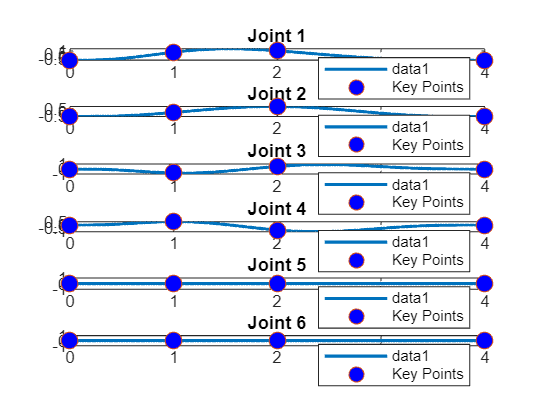


% Define key time points
tpts = [0, 1, 2, 4]; % Time for each waypoint

% Define total number of samples (300 steps)
numSamples = 1000;

% Generate minimum-jerk trajectory
[q, qd, qdd, ~, ~, ~, tvec] = minjerkpolytraj(Q_waypoints, tpts, numSamples);


% Plot Joint Positions
figure;
for i = 1:6
    subplot(6,1,i)
    plot(tvec, q(i, :), 'LineWidth', 1.5); 
    hold on;
    title(['Joint ', num2str(i)]); 
            % Overlay points
    plot(tpts, Q_waypoints(i, :), 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'b', 'DisplayName', 'Key Points');
    title(['Joint ', num2str(i)]);
    legend('show');
end
hold off;

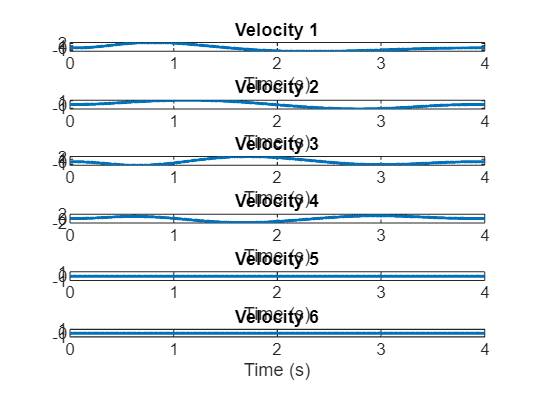


% Plot Joint Velocities
figure;
for i = 1:6
    subplot(6,1,i)
    plot(tvec(1:end), qd(i, :), 'LineWidth', 1.5); % Use tvec(1:end-1) to match qd size
    hold on;
    title(['Velocity ', num2str(i)]);
    xlabel('Time (s)');
    ylabel('Velocity (rad/s)');

end
hold off;

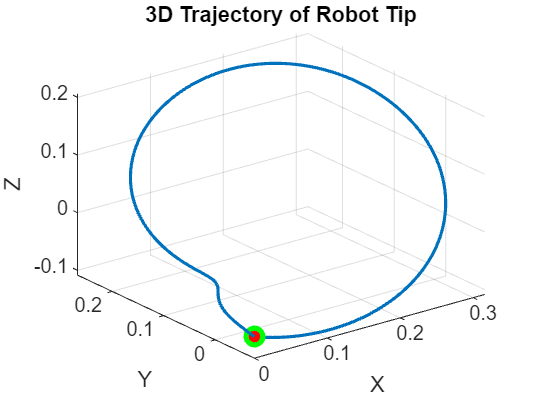

%initialise an array to store end-effector coordinates for each time step i
%rows= coordinate / column=tipe step
tip_positions = zeros(3, length(tvec)); % Initialize for end-effector positions

% Loop through each time-step created
for i = 1:length(tvec)
    
    %retrieve the theta values at step i from the interpolation Q(each row
    %a joint...the column are the interpolating values)
    %es: 1 iteration = step 1 ----get all 6 angles of the 6 joints
    joint_values = q(:, i); 
    
    %subs input:
    % 1) in which expression to  substitute (Q_t that is an array of 3 values
    % 2)which are the variables
    % 3)related values of those variables...(joint:values is a column...need
    % to be a row for subs)
    Q_numeric = subs(Q_t, [theta1, theta2, theta3, theta4, theta5, theta6], joint_values');
    
    % Store the end-effector position
    %each row is a coordinate: X, Y, Z
    tip_positions(:, i) = Q_numeric;
end

%PLOT 3D trajectory:
x = tip_positions(1, :); % Extract X-coordinates
y = tip_positions(2, :); % Extract Y-coordinates
z = tip_positions(3, :); % Extract Z-coordinates

figure;
plot3(x, y, z, 'LineWidth', 1.5); % Plot the trajectory
hold on;
plot3(x(1), y(1), z(1), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', 'Start'); % Start point (green filled circle)
plot3(x(end), y(end), z(end), 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r', 'DisplayName', 'End'); % End point (red filled circle)
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Trajectory of Robot Tip');
hold off;

% Connect to CoppeliaSim (connets the 2 softwares)
%define host and port
%
host = '127.0.0.1'; %means they are on the same PC
port = 23000;
client = RemoteAPIClient();
sim = client.require('sim');
fprintf('Connection to CoppeliaSim is successful.\n');

Connection to CoppeliaSim is successful.



% Providing MATLAB the name of the parts of the robot (defined in Coppelia)
Name_joints = {'/Mirobot/joint1', '/Mirobot/joint2', '/Mirobot/joint3', '/Mirobot/joint4', '/Mirobot/joint5', '/Mirobot/joint6'};
Handles_joints = zeros(length(Name_joints), 1);

for i = 1:length(Name_joints)
    Handles_joints(i) = sim.getObject(Name_joints{i});
end

%activitang the simulation on Coppelia
% myObj = Mirobot_Matlab; 
sim.startSimulation();
% s = myObj.Mirobotconnect(3); %connect to COM3 for example
disp('MATLAB connected to Mirobot');

MATLAB connected to Mirobot


pause(5);

%SIMULATION ON MATLAB and COPPELIA

figure;
%Sending simulation to Coppelia sim:
for i = 1:length(tvec)
    currentConfig = q(:, i); % Get joint positions
     % myObj.go_to_axis(s, rad2deg(currentConfig(1)), rad2deg(currentConfig(2)), rad2deg(currentConfig(3)), rad2deg(currentConfig(4)), rad2deg(currentConfig(5)), rad2deg(currentConfig(6)));
    % show(robot, currentConfig, "Collisions", "on", "Frames", "on");
    % drawnow;
    % Sending the same to CoppeliaSim
    for j = 1:length(Name_joints)
        sim.setJointTargetPosition(Handles_joints(j), currentConfig(j));
    end
end

%STOP this simulation to do not overlap with the next one
sim.stopSimulation();
pause(1);
